Create separated versions of the figs in plots_enzymepaper1e for use in presentations

overwritefiles = true;
%overwritefiles = false;

%clean and prep data
%d = dat(strcmpi('Fixed',dat.mode),:);
%d = d(strcmpi('1x1',d.layouttype),:);
%d = d(d.deathrate==0.00125,:);
%d = d(d.decayrate == 1/120,:);
%d = d(d.costfactor == 1,:);

d = dat3;

figpath = 'C:\sync\biomes\cellulose\optima\data_for_paper\figs\timeseries\';

%fill out extra columns
%d = populateColumnsForPaper1(d);
%d = cleanupGrowthRate(d);

Section 1: plot cellulose / glucose / enzyme / biomass / growthrate over time for three alphas

%alphas = pow2([-9 -11 -13]);

%kill a dumb rounding bug
d.log10alpha = round(log10(d.alpha),5);

alphas = [-1.5 -2 -2.5 -3 -3.5 -4];
d = d(ismember(d.log10alpha,alphas),:);
d = d(d.celscale == 1,:);
% d.log2alpha = log2(d.alpha);
% d.log10alpha = log10(d.alpha);
d = sortrows(d,'alpha','descend');
varIE = d.variableInitEnzyme(1);
colors = parula(length(alphas)+1);
colors = colors(1:end-1,:);
%colors = parula(length(alphas)+3);
%colors = colors(2:end,:);
%colors = lines(length(alphas));

xmax = 250;
yscale = 'log';
ymins = [1e-5 1e-4 1e-5 1e-7 1e-8]; %constantInitEnzyme
%yscale = 'linear';

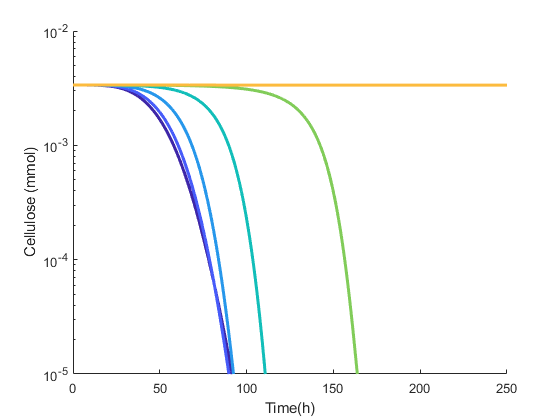


%subplot(3,2,1);
f = figure();
hold on
for i = 1:length(alphas)
    plot(t,d.cellulose_amt{i},'linewidth',2,'color',colors(i,:));
end
hold off;
%title('Cellulose');
ylabel('Cellulose (mmol)');
xlim([0 xmax]);
xlabel('Time(h)');
set(gca,'yscale',yscale);
if strcmp(yscale,'log')
    if varIE
     ylim([1e-5 1e-2]);
     yticks([1e-5 1e-4 1e-3 1e-2]);
    else
     ylim([1e-5 1e-2]);
     yticks([1e-5 1e-4 1e-3 1e-2]);
    end
end

if overwritefiles
saveas(f,[figpath 'cellulose.png']);
end

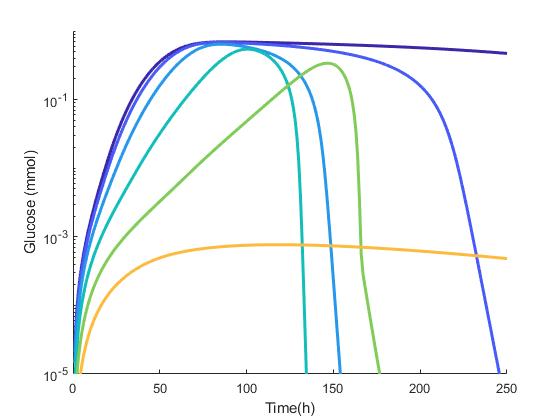


%subplot(3,2,3);
f = figure();
hold on;
for i = 1:length(alphas)
    plot(t,d.glc_amt{i},'linewidth',2,'color',colors(i,:));
end
hold off;
%title('Glucose');
ylabel('Glucose (mmol)');
xlim([0 xmax]);
xlabel('Time(h)');
set(gca,'yscale',yscale);
if strcmp(yscale,'log')
    if varIE
     ylim([1e-2 1]);
     %yticks([1e-4 1e-2 1e0]);
    else
     ylim([1e-5 1]);
     %yticks([1e-4 1e-2 1e0]);
     yticks([1e-5 1e-3 1e-1]);
    end
end
if overwritefiles
saveas(f,[figpath 'glucose.png']);
end

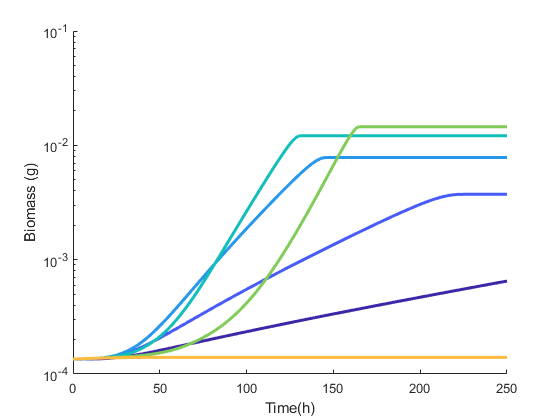


%subplot(3,2,2);
f = figure();
hold on;
for i = 1:length(alphas)
    plot(t,d.biomass{i},'linewidth',2,'color',colors(i,:));
end
hold off;
%title('Biomass');
ylabel('Biomass (g)');
xlim([0 xmax]);
xlabel('Time(h)');
set(gca,'yscale',yscale);
if strcmp(yscale,'log')
    if varIE
     ylim([1e-4 1e-1]);
     yticks([1e-4 1e-3 1e-2 1e-1]);
    else
     ylim([1e-4 1e-1]);
     yticks([1e-4 1e-3 1e-2 1e-1]);
    end
end
if overwritefiles
saveas(f,[figpath 'biomass.png']);
end

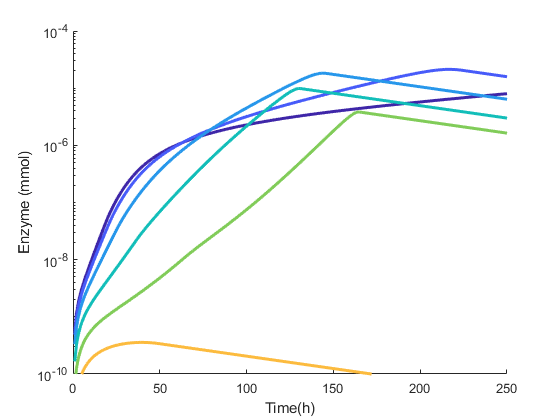

f = figure();
%subplot(3,2,5);
hold on;
for i = 1:length(alphas)
    plot(t,d.enzyme_amt{i},'linewidth',2,'color',colors(i,:));
end
hold off;
%title('Enzyme');
ylabel('Enzyme (mmol)');
xlim([0 xmax]);
xlabel('Time(h)');
set(gca,'yscale',yscale);
if strcmp(yscale,'log')
    if varIE
     ylim([1e-9 1e-4]);
     yticks([1e-8 1e-6 1e-4]);
    else
     %ylim([1e-8 1e-3]);
     %yticks([1e-7 1e-5 1e-3]);
     ylim([1e-10 1e-4]);
     yticks([1e-10 1e-8 1e-6 1e-4]);
    end
end
if overwritefiles
saveas(f,[figpath 'enzyme.png']);
end

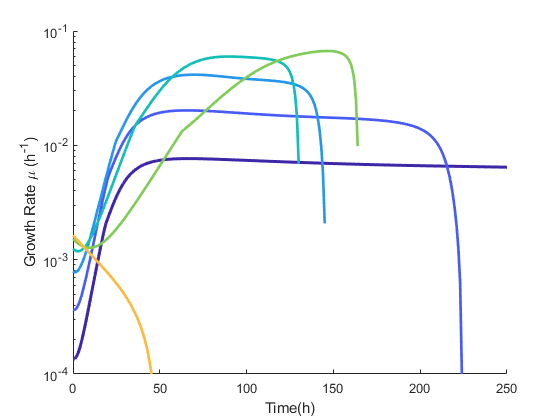

f = figure();
%subplot(3,2,4);
hold on;
for i = 1:length(alphas)
    bio = d.biomass{i};
    biodelta = bio(2:end) - bio(1:end-1);
    mu = biodelta ./ bio(1:end-1);
    plot(t(1:end-1),mu,'linewidth',2,'color',colors(i,:));
end
hold off;
%title('Growth Rate');
ylabel('Growth Rate \mu (h^-^1)');
xlim([0 xmax]);
xlabel('Time(h)');
set(gca,'yscale',yscale);
if strcmp(yscale,'log')
    if varIE
     ylim([1e-7 1e-2]);
     yticks([1e-6 1e-4 1e-2]);
    else
     %ylim([1e-7 1e-2]);
     %yticks([1e-6 1e-4 1e-2]);
     ylim([1e-4 1e-1]);
     yticks([1e-4 1e-3 1e-2 1e-1]);
    end
end
if overwritefiles
saveas(f,[figpath 'growthrate.png']);
end

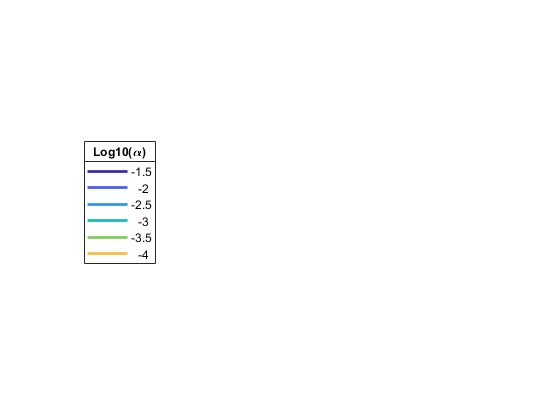

f = figure();
%subplot(3,2,6);
hold on;
for i = 1:length(alphas)
    plot(NaN,NaN,'LineWidth',2,'color',colors(i,:));
end
hold off;
leg = legend(num2str(alphas'),'location','west');
set(gca,'Visible','off');
title(leg,'Log10(\alpha)');
hold off;
if overwritefiles
saveas(f,[figpath 'legend.png']);
end

#### Bonus figures

Fig 1: comparing end of growth and end of cellulolysis

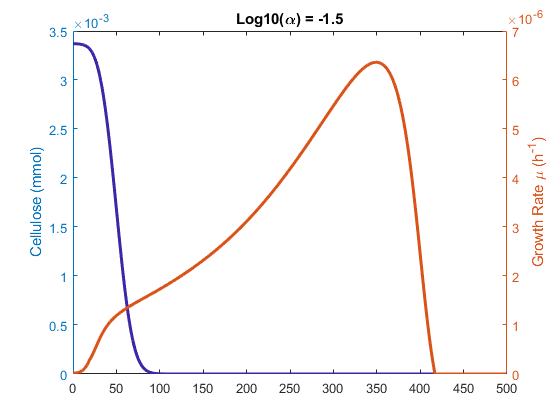

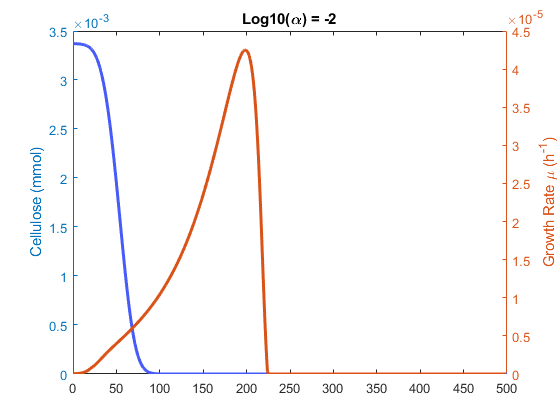

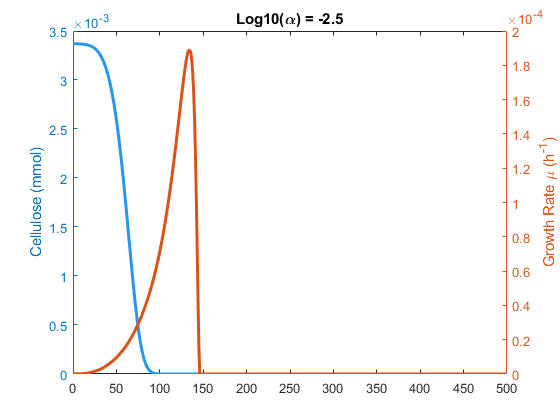

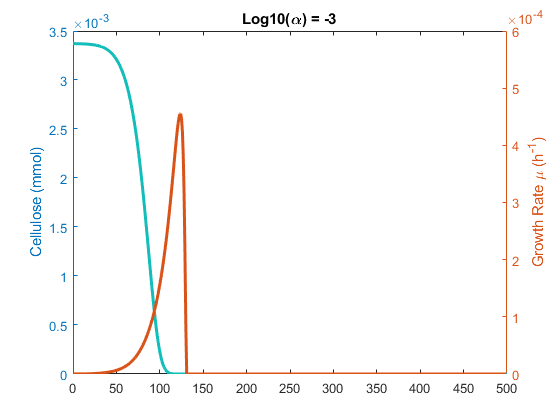

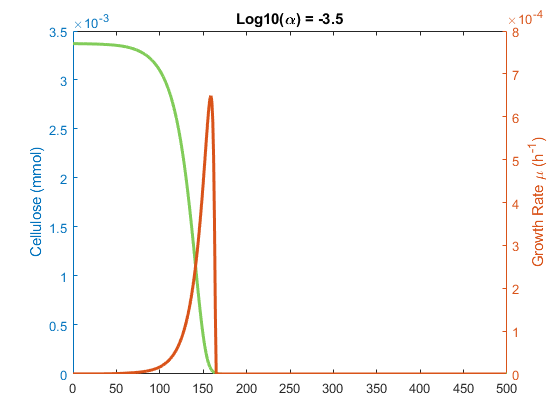

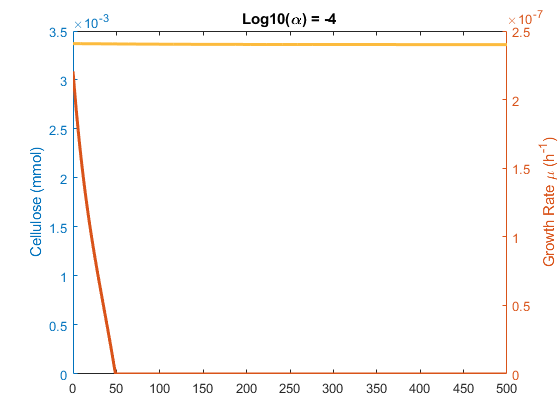

yscale = 'linear';
for i = 1:length(alphas)
figure();
yyaxis left;
plot(t,d.cellulose_amt{i},'linewidth',2,'color',colors(i,:));
ylabel('Cellulose (mmol)');
ylim([0, 3.5e-3]);
if strcmp(yscale,'log')
    if varIE
     ylim([1e-5 1e-2]);
     yticks([1e-5 1e-4 1e-3 1e-2]);
    else
     ylim([1e-5 1e-2]);
     yticks([1e-5 1e-4 1e-3 1e-2]);
    end
end
yyaxis right;
bio = d.biomass{i};
biodelta = bio(2:end) - bio(1:end-1);
plot(t(1:end-1),biodelta,'linewidth',2);
ylabel('Growth Rate \mu (h^-^1)');
%set(gca,'yscale',yscale);
if strcmp(yscale,'log')
    if varIE
     ylim([1e-7 1e-2]);
     yticks([1e-6 1e-4 1e-2]);
    else
     %ylim([1e-7 1e-2]);
     %yticks([1e-6 1e-4 1e-2]);
     ylim([1e-8 1e-3]);
     yticks([1e-7 1e-5 1e-3]);
    end
end
title(['Log10(\alpha) = ' num2str(alphas(i))]);
end

** Enzyme production rates vary by roughly the same scale as enzyme concentrations, despite growth rates being very different**

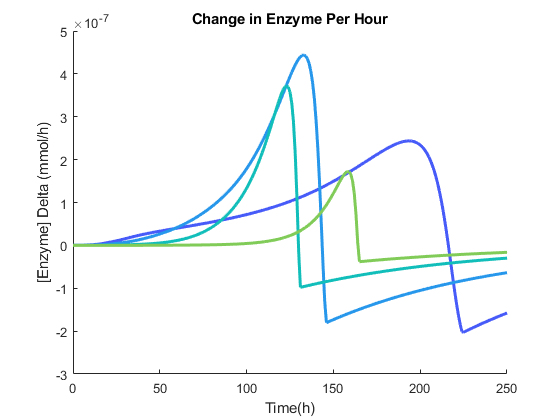

yscale = 'linear';
alphas_t = [-1.5 -2 -2.5 -3 -3.5];
f = figure();
%subplot(3,2,5);
hold on;
maxes_delta = zeros(1,4);
for i = 2:length(alphas_t)
    amt = d.enzyme_amt{i};
    enzdelta = amt(2:end) - amt(1:end-1);
    maxes_delta(i-1) = max(enzdelta);
    plot(t(1:end-1),enzdelta,'linewidth',2,'color',colors(i,:));
end
hold off;
%title('Enzyme');
ylabel('[Enzyme] Delta (mmol/h)');
xlim([0 xmax]);
xlabel('Time(h)');
set(gca,'yscale',yscale);
title('Change in Enzyme Per Hour');
if overwritefiles
saveas(f,[figpath 'enzdelta.png']);
end

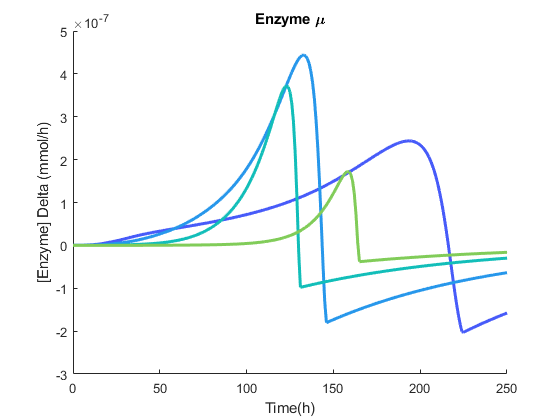



f = figure();
%subplot(3,2,5);
hold on;
maxes_delta = zeros(1,4);
for i = 2:length(alphas_t)
    amt = d.enzyme_amt{i};
    enzdelta = amt(2:end) - amt(1:end-1);
    maxes_delta(i-1) = max(enzdelta);
    plot(t(1:end-1),enzdelta,'linewidth',2,'color',colors(i,:));
end
hold off;
%title('Enzyme');
ylabel('[Enzyme] Delta (mmol/h)');
xlim([0 xmax]);
xlabel('Time(h)');
set(gca,'yscale',yscale);
title('Enzyme \mu');
if overwritefiles
saveas(f,[figpath 'enzdelta.png']);
end

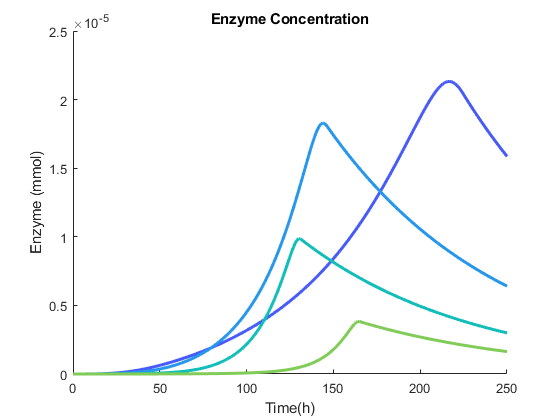



f = figure();
%subplot(3,2,5);
maxes_con = zeros(size(maxes_delta));
hold on;
for i = 2:length(alphas_t)
    maxes_con(i-1) = max(d.enzyme_amt{i});
    plot(t,d.enzyme_amt{i},'linewidth',2,'color',colors(i,:));
end
hold off;
%title('Enzyme');
ylabel('Enzyme (mmol)');
xlim([0 xmax]);
xlabel('Time(h)');
set(gca,'yscale',yscale);
title('Enzyme Concentration');
if strcmp(yscale,'log')
    if varIE
     ylim([1e-9 1e-4]);
     yticks([1e-8 1e-6 1e-4]);
    else
     %ylim([1e-8 1e-3]);
     %yticks([1e-7 1e-5 1e-3]);
     ylim([1e-10 1e-4]);
     yticks([1e-10 1e-8 1e-6 1e-4]);
    end
end

if overwritefiles
saveas(f,[figpath 'enzyme_linear.png']);
end


f = figure();
%subplot(3,2,4);
maxes_growth = zeros(size(maxes_delta));
hold on;
for i = 2:length(alphas_t)
    bio = d.biomass{i};
    biodelta = bio(2:end) - bio(1:end-1);
    mu = biodelta ./ bio(1:end-1);
    plot(t(1:end-1),mu,'linewidth',2,'color',colors(i,:));
    maxes_growth(i-1) = max(mu)
end

maxes_growth =     0.0202         0         0         0


maxes_growth =     0.0202    0.0415         0         0


maxes_growth =     0.0202    0.0415    0.0598         0


maxes_growth =     0.0202    0.0415    0.0598    0.0669


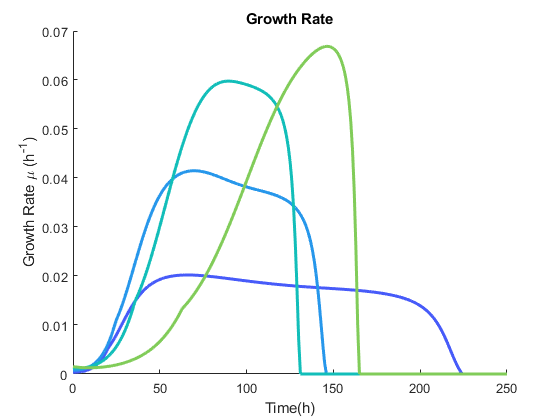

hold off;
%title('Growth Rate');
ylabel('Growth Rate \mu (h^-^1)');
xlim([0 xmax]);
xlabel('Time(h)');
title('Growth Rate');
set(gca,'yscale',yscale);
if strcmp(yscale,'log')
    if varIE
     ylim([1e-7 1e-2]);
     yticks([1e-6 1e-4 1e-2]);
    else
     %ylim([1e-7 1e-2]);
     %yticks([1e-6 1e-4 1e-2]);
     ylim([1e-4 1e-1]);
     yticks([1e-4 1e-3 1e-2 1e-1]);
    end
end
if overwritefiles
saveas(f,[figpath 'growthrate_linear.png']);
end


maxes_delta

maxes_delta = 	1.0e+-6 *

    0.2436    0.4440    0.3723    0.1724


dif_delta = max(maxes_delta) / min(maxes_delta)

dif_delta = 2.5756


maxes_con

maxes_con = 	1.0e+-4 *

    0.2133    0.1830    0.0986    0.0383


dif_con = max(maxes_con) / min(maxes_con)

dif_con = 5.5743


maxes_growth

maxes_growth =     0.0202    0.0415    0.0598    0.0669


dif_growth = max(maxes_growth) / min(maxes_growth)

dif_growth = 3.3082

Just grab the other linears

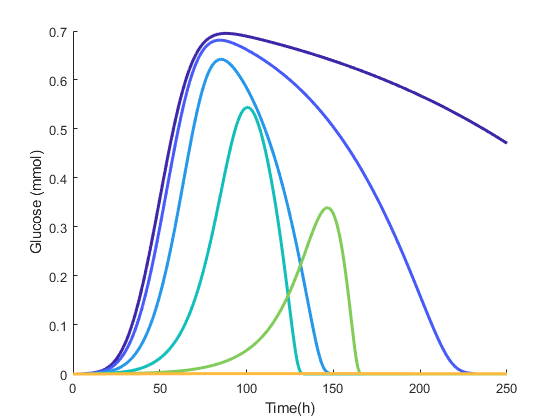

yscale = 'linear';
f = figure();
hold on;
for i = 1:length(alphas)
    plot(t,d.glc_amt{i},'linewidth',2,'color',colors(i,:));
end
hold off;
%title('Glucose');
ylabel('Glucose (mmol)');
xlim([0 xmax]);
xlabel('Time(h)');
set(gca,'yscale',yscale);
if strcmp(yscale,'log')
    if varIE
     ylim([1e-2 1]);
     %yticks([1e-4 1e-2 1e0]);
    else
     ylim([1e-5 1]);
     %yticks([1e-4 1e-2 1e0]);
     yticks([1e-5 1e-3 1e-1]);
    end
end
if overwritefiles
saveas(f,[figpath 'glucose_linear.png']);
end

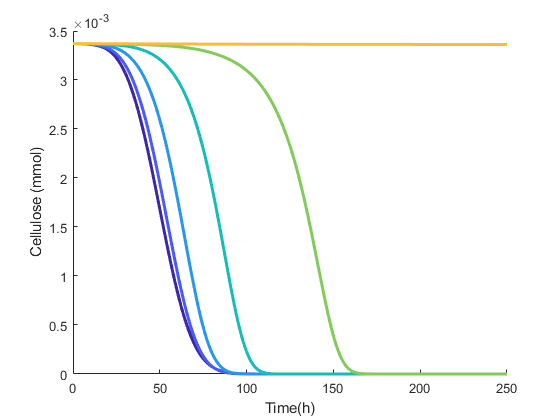


f = figure();
hold on
for i = 1:length(alphas)
    plot(t,d.cellulose_amt{i},'linewidth',2,'color',colors(i,:));
end
hold off;
%title('Cellulose');
ylabel('Cellulose (mmol)');
xlim([0 xmax]);
xlabel('Time(h)');
set(gca,'yscale',yscale);
if strcmp(yscale,'log')
    if varIE
     ylim([1e-5 1e-2]);
     yticks([1e-5 1e-4 1e-3 1e-2]);
    else
     ylim([1e-5 1e-2]);
     yticks([1e-5 1e-4 1e-3 1e-2]);
    end
end

if overwritefiles
saveas(f,[figpath 'cellulose_linear.png']);
end

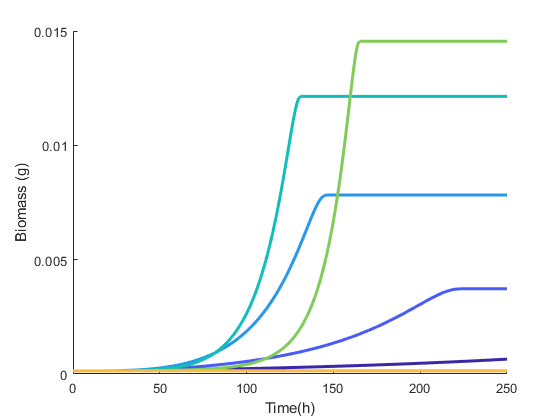


%subplot(3,2,2);
f = figure();
hold on;
for i = 1:length(alphas)
    plot(t,d.biomass{i},'linewidth',2,'color',colors(i,:));
end
hold off;
%title('Biomass');
ylabel('Biomass (g)');
xlim([0 xmax]);
xlabel('Time(h)');
set(gca,'yscale',yscale);
if strcmp(yscale,'log')
    if varIE
     ylim([1e-4 1e-1]);
     yticks([1e-4 1e-3 1e-2 1e-1]);
    else
     ylim([1e-4 1e-1]);
     yticks([1e-4 1e-3 1e-2 1e-1]);
    end
end
if overwritefiles
saveas(f,[figpath 'biomass_linear.png']);
end